Uncertainty in electrical components    

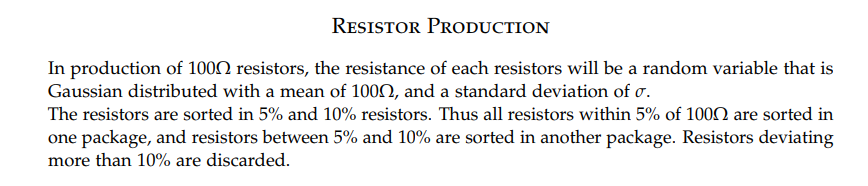

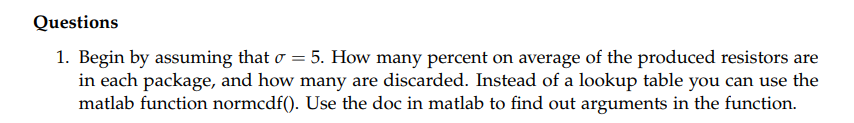

%% Question 1: How many percent of the produced resistors are in each package
% We have the standard deviation sigma=2
mu=100;
sigma=5;


% 5% under 100 Ohm er 95 Ohm
P_CDF95 = normcdf(95,mu,sigma); %Probability for x<95

%Probability of getting a value below 95 and above 105, since Gaussian
%function is symetric, we find the percentage
Prob95=2*(P_CDF95)*100

Prob95 = 31.7311


% 110% under 110 Ohm er 95 Ohm
P_CDF90 = normcdf(90,mu,sigma); %Probability for x<95

%Probability of getting a value below 95 and above 105, since Gaussian
%function is symetric, we find the percentage
Prob90=2*(P_CDF90)*100

Prob90 = 4.5500


%CDF skal slås op i en tabel

% The result is that 31,7% derivate with more than 5%.
% Of these derivate 4,6% more than 10%
% This means that 100%-31,7% = 68.3% is within 5%
% And that 31,7%-4,6%=27,1% is between 5%-10%
% 4,6% is discarded and above 10%.

%% Question 2: Simulation of question 1
nResistor=1000;
DiscardedR=0;
Res10pr=0;
Res5pr=0;
Res=sigma*randn(1,nResistor)+mu;

for n=1:nResistor
   if  Res(n)>110 || Res(n)<90
      DiscardedR= DiscardedR+1;
      
   else if Res(n)>105 || Res(n)<95
       Res10pr=Res10pr+1;
       else 
    Res5pr=Res5pr+1;       
       end
       
   end
end

%Percentage of resistor discarded:
DisSim= 100*DiscardedR/nResistor

DisSim = 4.4000


%Percentage of 10% resistor:
Sim10=100*Res10pr/nResistor

Sim10 = 27.5000


%Percentage of 5% resistor:
Sim5=100*Res5pr/nResistor

Sim5 = 68.1000

%% Question 3: 
SigmaNy=sigma;
for n=1:10000
    if 95<norminv(0.25,mu,SigmaNy)
SigmaNy=SigmaNy+0.001;
    end
end
SigmaNy

SigmaNy = 7.4140

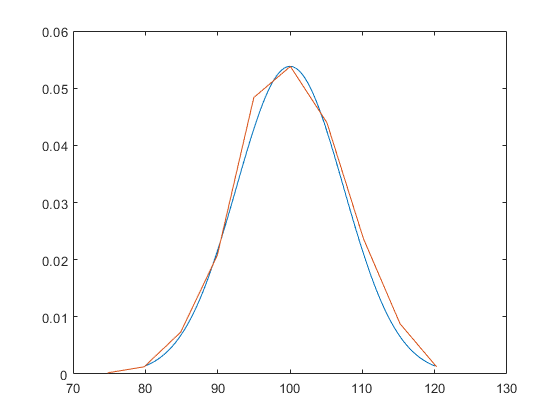



%% Question 4: Plot the pdf and cdf
nResistors=1000;

resistors=SigmaNy*randn(1,nResistors)+mu;
%resistors=resistors./nResistors;
close all
figure(1)
plot(80:0.1:120,normpdf(80:0.1:120,mu,SigmaNy))
hold on
maxpdf=max(normpdf(80:0.1:120,mu,SigmaNy));
[b vaerdi]=hist(resistors);
b=b.*maxpdf/max(b);
plot(vaerdi,b)

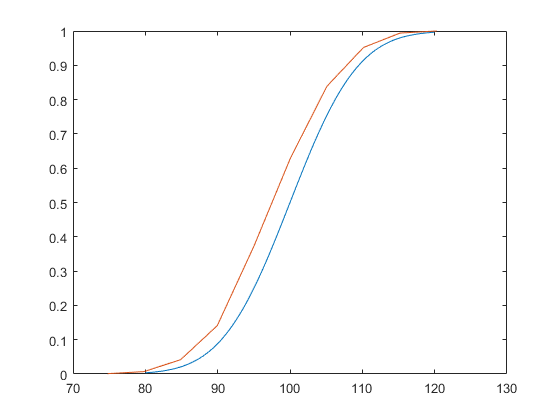


% plot cdf

bCDF(1)=b(1);
for n=2:length(b)
   bCDF(n)=bCDF(n-1)+b(n); 
    
end
bCDF=bCDF./max(bCDF);

figure(2)
plot(80:0.1:120,normcdf(80:0.1:120,mu,SigmaNy))
hold on
plot(vaerdi,bCDF)

%% Question 5
% standard deviation
STRes=sqrt(var(resistors));

%Mean value
MERes=mean(resistors);

%% Question 6
%The sample size is not large enough